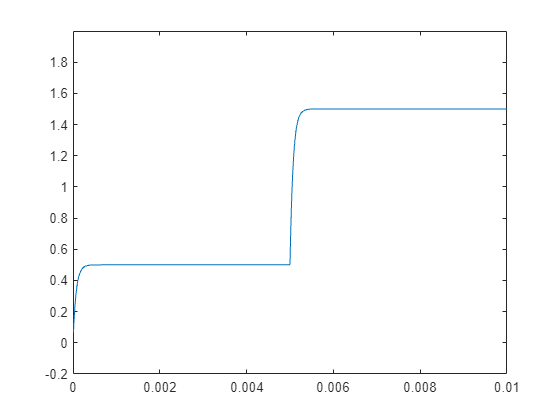

clear all; close all; clc;

%% Square wave
syms t s square
f = 100;
T = 1/f;
w = 2 * pi * f;
amplitude = 1;
offset = 0.5;
square = amplitude *heaviside(t - T/2) - amplitude *heaviside(t - T) + offset * heaviside(t);


%% Circuit A
syms C1 R response1(t, R, C1)
response1(t, R, C1) = ilaplace(laplace(square) * (1/(s*C1))/(R + 1/(s*C1)));
steps = 1000;
step = T/steps;
t = step:step:T;
x = response1(t, 1.5e3, 47e-9);
figure('Name','Circuit A')
plot(t, x)
ylim([-0.2, 2])


%% Circuit B
syms C2 R response2(t, R, C2)
response2(t, R, C2) = ilaplace(laplace(square) * R/(R + 1/(s*C2)));
steps = 1000;
step = T/steps;
t = step:step:T;
x = response2(t, 1.5e3, 10e-9)

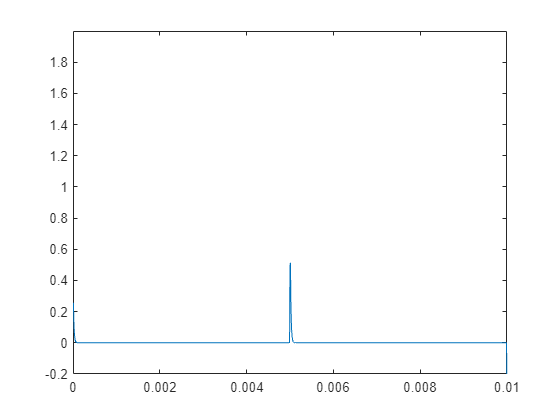

figure('Name','Circuit B')
plot(t, x)
ylim([-0.2, 2])


%% Circuit C
syms R1 R2 C1 L1 response33(t, C1, L1) response32(t, C1, L1, R2) response(t, C1, L1, R1)
response33(t, C1 , L1) = ilaplace(laplace(square) * (s*L1)/(s*L1 + 1/(s*C1)))

$$response33(t, C1, L1) = \frac{\cos\left(\frac{t}{\sqrt{C_{1}}\,\sqrt{L_{1}}}\right)}{2}-\mathrm{heaviside}\left(t-\frac{1}{100}\right)\,\cos\left(\frac{t-\frac{1}{100}}{\sqrt{C_{1}}\,\sqrt{L_{1}}}\right)+\mathrm{heaviside}\left(t-\frac{1}{200}\right)\,\cos\left(\frac{t-\frac{1}{200}}{\sqrt{C_{1}}\,\sqrt{L_{1}}}\right)$$

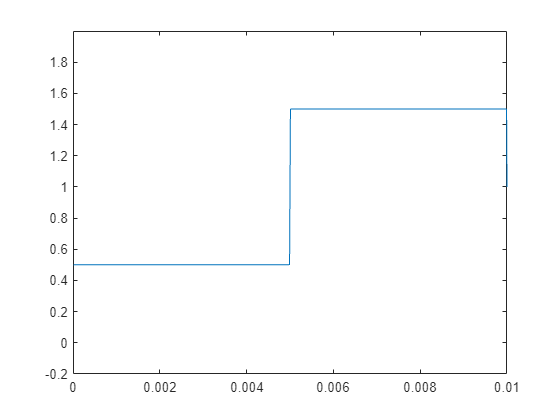

steps = 1000;
step = T/steps;
t = step:step:T;
x = response33(t, 33e3, 10e-3);
figure('Name','Circuit C33')
plot(t, x)
ylim([-0.2, 2])